# To test different models for lattice characterization

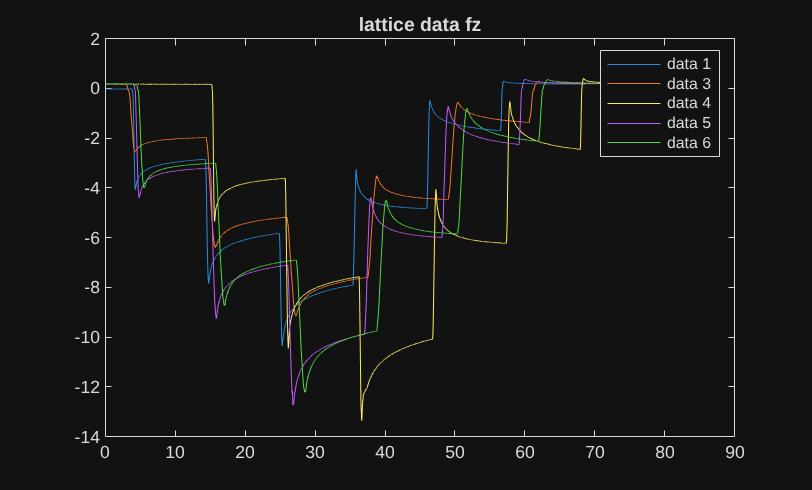

% index = ['1';'2';'6';'7';'8';'9']; % for trial4
index = ['1';'3';'4';'5';'6']; % for trial3
% folder = "lattice_calibration_data/15x15x15/trial4/";
folder = "lattice_calibration_data/15x15x15/trial3/";
figure;
for i=1:size(index,1)
    filename = folder + "lattice_data_" + index(i) + ".mat";
    load(filename);
    plot(t_biased,fz);
    title("lattice data fz");
    hold on;
end
legend("data "+index);
hold off;

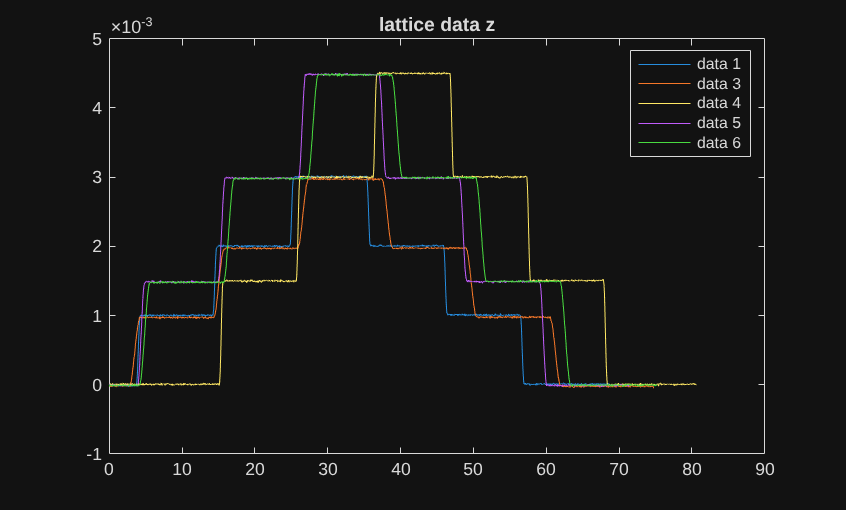


figure
for i=1:size(index,1)
    filename = folder + "lattice_data_" + index(i) + ".mat";
    load(filename);
    plot(t_biased,z);
    title("lattice data z");
    hold on;
end
legend("data "+index);
hold off;

% fz_estimated = estimate_lattice_force(z,t_biased,back_track,k,r1,r2,time_window);

% figure;
% plot(t_biased,fz,"LineWidth",1.3,"Color","red");
% hold on;
% plot(t_biased,fz_estimated,"LineWidth",1.3,"Color","green");
% grid on;
% xlabel("Time(s)");
% ylabel("Force(N)");
% legend(["Measured Force","Estimated Force"]);
% title("Measured Force vs Estimated Force");